# PolitoCliDyn: first-order carbon cycle LiveScript

Authors E.Canuto, C.Novara, A.D'Apice, Politecnico di Torino, Torino, Italy, June  2024

Code, with extensions, of the paper:

E.Canuto, D.Mazza and C. Novara, Projection of the airborne CO2 concentration by land/ocean absorption dynamics and fossil-fuel reserve depletion, *Environmental Modelling & Assessment*, 2024, https://doi.org/10.1007/s10666-024-09985-7

## Acronyms

AFOLU     agriculture, forestry and other land use

CAT      Climate Action Tracker (data source)

CC        carbon cycle

CD        carbon dioxide (${\textrm{CO}}_{2\;}$)

CliDyn   Climate Dynamics

FF         fossil fuel (oil, natural gas=methane, coal and lignite)

GCP       Global Carbon Project (data source)

IIASA     International Institute for Applied Systems Analysis (data source)   

IPCC      Intergovernmental Panel on Climate Change (data source)

LTI          linear time invariant

MAGICC    Model for the Assessment of Greenhouse Gas Induced Climate Change (data source)

NaN          denotes, in the code Tables, either a quantity of no interest or non computable

OWID        Our-World-in-Data (data source)

ppm          ratio between amount of CD moles and amount of dry air moles in a given volume, reported as a part per million (concentration unit)

ppm/y       part per milion per year (CD concentration rate unit)

Polito         Politecnico di Torino

RMS          root mean square

std             standard deviation

SSP           Shared Socioeconomic Pathway (future emission scenario)

$\left\lbrack {\textrm{Gm}}^{3\;} ={10}^{9\;} {\mathrm{m}}^{3\;} \right\rbrack$  square brackets denote measurement units

## Summary

A first-order LTI dynamics of the mean global carbon cycle is identified though global airborne CD concentration data [ppm] and reconstructed FF emissions [ppm/y] since 1850. FF emission history is projected to the future, constrained by predicted proven FF reserves (oil, natural gas and coal). In turn, the data-fit CC dynamics, driven by the projected emissions, forecast the future airborne CD concentration. Comparison is made with CAT, IIASA, IPCC and MAGICC predictions. Discrepancies are shown recoverable by first-order quadratic dynamics.

## Input data

They are arranged into subfolders of **PolitoCliDyn_InData**.

1) **CAT**, projected airborne CD concentration data from Climate Action Tracker, see Part III, Fig.11

2) **GCP**, historical CD emission data from Global Carbon Project, to be usedin Part I and Part III.  See Part I, Figs. 2 to 3, and Part III, Figs. 1 and 2

3) **IIASA**, projected CD emission data from International Institute for Applied Systems Analysis, to be used in Part III and Part IV. See Part III, Fig. 12 and Part IV, Fig. 5

4) **IPCC Tables**, projected airborne CD concentration data from the Intergovernmental Panel on Climate Change , to be used in Part IV, see Figs. 5 to 7. Only a subset of the projection files have been employed.

5) **MAGICC**, projected CD emission and airborne CD concentration data from the online Model for the Assessment of Greenhouse Gas Induced Climate Change, to be used in Part IV (only SSP 460), see Fig. 8

6) **OWID**, historical fossil-fuel proven reserves, consumption and CD emissions by fuel data, from Our-World-in-Data, to be used in Part II, see Figs. 2 to 4

7) **Scripps Research**, historical airborne CD concentration data to be used in Part I, see Fig. 1 to 3.

**CAVEAT: users are suggested to save a copy of PolitoCliDyn_InData. Any change may produce unexpected results and/or code failure. The code is only protected against missing or renamed files, when the folder PolitoCliDyn_OutData has reached convergence (see below 'Output data'). File not found is signalized, the relevant Part exits, but LiveScript keeps running based on either PolitoCliDyn_OutData or default values.**

## **Output data**

**A) Numerical data** are arranged in PolitoCliDyn_OutData (xlsx and mat files).

1) **CDFitParameterTable_PartI **(mat and xlsx) contains for each item of the rolling regression (`ParamFit`x, x=1 to 151 in the mat file, x=1,11,...,151 in the xlsx file), a parameter table of the three regression (difference, integral, cumulative) results: mean values, std, residuals and statistical indices. ParamCommon contains common data to regressions. The mat file is read in Part IV for building CD concentration projections.CAVEAT: if renamed or deleted, Part IV exits unless Part I has been previously run.

2) **CDFitTimeTable_PartI** (mat and xlsx) contains the time profiles (`TimeFitx`, x=1 to 151 in the mat file, x=1,11,...,151 in the xlsx file) of the raw CD concentration data, estimate and residuals of the three regressions. History contains the historical time profiles of the airborne CD concentration and the CD emission by fossil fuel combustion. Historical CD data are read in Part IV from mat file. CAVEAT: if renamed or deleted, Part IV exits unless Part I has been previously run.

3) **RollingFitTable..mat **contains the initial times of the rolling time regressions to be used in Parts I, III and IV. CAVEAT: if renamed or deleted, Part III and IV exit unless Part I has been previously run..

4) **PredReserve_PartII .mat** contains a table of three columns with the predicted reserves and std of oil, gas and coal, to be read in Part III. CAVEAT:  if renamed or deleted, Part III exits unless Part II has been previously run.

5) **FFEInitTab_PartIII.mat **contains for each fuel (third coordinate from 1 to 3), for each bound (mean, upper and lower, column from 1 to 9) and for each regression (row from 1 to 151), the most recent estimates by `fminsearch` of the Meixner parameters (amplitude [ppm/y], time constant [y] and peak time [y]). The row order is mean parameters, upper bound parameters, lower bound parameters. A richer set of results of the regressions x=1,11,...,151 can be found in the sheets `Parameters iFit=x` of FFEFitParameterTable_PartIII.xlsx.

CAVEATS: 1) the estimates change by changing tEndUser. 2) If either deleted or renamed, default internal values are employed and tEndUser is set to about 2200. The anomaly is signalized and the file is rebuilt.

6) **FFEPriorStd_PartIII.mat **contains the most recent measurement std to be used in each regression. The measurement std is reconstructed a posteriori from the estimate residuals. It depends on each regression, but not on time. CAVEAT: if renamed or deleted, the anomaly is signalized, internal default values are employed, tEndUser is set to about 2200 and the file is rebuilt.

7) **FFETotPredictionTable_PartIII.mat **contains for each regression (`Totx`, x=1 to 151), the total emission profiles (mean, upper bound, lower bound) of fossil fuels (columns 2, 3  and 4). The first column is the time  [y]. The emission profiles include historical data and projections. The profiles are read and used in Part IV. CAVEAT: if deleted or renamed, Part IV exits unless Part III has been previously run.

8) **FFEPredictionTable_PartIII.xlsx** contains in the sheets `Projection iFit=x`  the time profiles of each fuel CD emission for the projections x=1,11,...,151.

9) **CDPredictionTable_PartIV.xlsx** contains in the sheets "Projection iFit=x"  the mean, upper and lower time profiles of the airborne CD concentration for the projections x=1,11,...,151.

**B) Plot images** are saved in `PolitoCliDyn_Figures` (png images). 

**CAVEAT: the code has been tested to converge from an empty PolitoCliDyn_OutData, in absence of PolitoCliDyn_InData anomalies. Users are suggested to ascertain convergence, after having saved the package folder. Convergence occurs when the **`fminsearch`** iterations of Part III (logSearch=1) become horizontal lines (2 steps for oil and gas, 3 steps for coal), under szIter=500,  tSelFit=1950 and tEndUser=2200. Convergence must be restored after changing tEndUser. **

## User input 

**CAVEAT: even if the range of the numerical sliders and spinners is changed by users, the code value is forced within the default range. When the user value is out of the default range, a warning signals that the user value has been corrected .**

% ACTION: section to be run first
szIter=500;
tSelFit = 1950;
uBandProb = 0.9;
tEndUser = 2200;
userGraphs = 1;
logSearch = 1;
% ACTION: users to change mlxFolder name to their own
mlxFolder="E:/Dati/ProjectResearch/CarloNovara/Climate/Code/PolitoCliDyn_1stOrderCC_code/PolitoCliDyn_1stOrderCC_Main";
try
    cd(mlxFolder);
catch
    error('WARNING: LiveScript halts, check mlxFolder name!');
end
CheckLiveScriptFolder;

PolitoCliDyn: 1st order CC: checking Live Script folder
DONE: PolitoCliDyn_1stOrderCC_LiveScript.mlx found
DONE: Live Script folder


userInputToggleFun; 

PolitoCliDyn: 1st order CC: saving user input data
DONE: ../PolitoCliDyn_OutData/userInputToggle.mat has been created


**szIter=max number of **`fminsearch`** iterations**

The positive integer `szIter` is the variable factor of the maximum number of iterations of the MATLAB function `fminsearch, `equal to `szIter x `size of unknowns`. T`he fixed range is 500 to 800. The least value is the `fminsearch `default.

**tSelFit=selected regression **

The positive integer `tSelFit` rappresents the initial regression year ,whose results are plotted and written in the `LiveScript`. The fixed range is 1940 to 1980. CAVEAT: the uncertainty band in Fig.1 of Part IV significantly increases from 1940 to 1980 in agreement with Fig.7 of Part I.

**uBandProb=uncertainty band**

The positive real uBandProb is the total probability of the uncertainty bands plotted by colored shades around result variables.  The fixed range is 0.9 to 0.9973. The least value corresponds to the "very likely" band of IPCC documents. A $3\sigma$ - band corresponds to `uBandProb = 0.9973.` Please notice that  some uncertainty bands are by default plotted as $3\sigma$-bands.

**tEndUser=projection end time**

The next choice concerns Part III and Part IV. The Boolean `logtEnd` toggles the user choice (`=1`) of the end time (`tEndUser`) of the projecton in Parti III of the finite-reserve CD emissions and in Part IV the projection of airborne CD concentration. The fixed range is 2150 to 2250.   The default value, 2200, balances past and future.

**userGraphs=saving graphical plots**

The Boolean `userGraphs` toggles saving (=1) graphical plots as png images in the the folder  .`.\PolitoCliDyn_Figure`s. The files are named by `PartX_Fig_Y_Day_Month_Year.png` and are replaced by successive daily runs. Folder cleaning along several days as well as daily saving is left to users. Undocked Matlab images can be cleared by `close all `in the `Command Window`.

**logSearch=plot of **`fminsearch`** iterations**

The Boolean `logSearch` toggles the semilogy plot of the `fminsearch` iterations (`=1`)  of the different code parts:

1) Part I: difference and integral regressions selected by tSelFit

2) Part II: the three regressions (oil, gas and coal)  that estimate the proven reserve uper limit

3) Part III: the three regressions (mean, upper and lower final reserve) for the three fossil fuels  (oil, gas and coal) , which estimate and project the finite-reserve CD emission pofiles

4) Part IV: the two regressions (difference and integral) that estimate the paramers of the first-order quadratic equation from IPCC data.

**CheckLiveScriptFolder **

If called from the right LiveScript folder, adds sub-folders to Matlab search path.

**userInputToggleFun=saving user parameters**

If called from the right LiveScript folder, the set of user parameters is saved, allowing `Run Section`

## Parti I

The first-order LTI state equation

 $\dot{x} \left(t\right)=-k\left(x\left(t\right)-\underline{x} \right)+u\left(t\right),x\left(t_{0\;} \right)=x_{0\;}$, 

with unknown parameters $k\;\left\lbrack y^{-1\;} \right\rbrack$ , pole, and $\underline{x\;} \left\lbrack \textrm{ppm}\right\rbrack$ , pre-industrial airborne CD equilibrium, is identified through global data of the CD annual mean concentration $x\left(t\right)\;\left\lbrack \textrm{ppm}\right\rbrack$ and of the annual FF by-combustion emission $u\left(t\right)\;\left\lbrack {\textrm{ppm}\;y}^{-1\;} \right\rbrack$ (Figs. 1 to 3). A rolling-time regression (Fig.7), $t_0 \le t\le t_p$ is performed by progressively, year-by-year, shifting the initial time $t_0 \ge 1850\;y$ toward the present $t_p =202\mathrm{0}\;\mathrm{y}$, until permitted by a statistical F-test, which defines the *red forbidden region* of Fig.8 ($t_0 >2000\;y$, `forbidden t0` in Table 1).  The  *pink not recommended region* is found by the residual RMS in Fig.9. Users can select, within the *selection region*, the initial time $1940\le t_0 \le 1980$  (`tSelFit` in the `User Input` section, `SelFit tInit` in Table 1) of the regression, whose results are graphically shown in Figs. 4 to 6 and in Tables 2 to 4. The estimated equilibrium $\underline{\widehat{x} }$, if close (see Fig. 7) to the pre-industrial estimate from historical data, plays the role of an implicit test of coherence betwen raw data and model. As a check, regression is repeated twice by fitting both the airborne CD concentration rate (*difference fit*) and the CD concentration raw data  (*integral fit*). As a further check, the model identified by the *difference fit* is integrated (*cumulative fit*). Residuals are compared in Fig.6.

#### Part I run

CheckLiveScriptFolder;

PolitoCliDyn: 1st order CC: checking Live Script folder
DONE: PolitoCliDyn_1stOrderCC_LiveScript.mlx found
DONE: Live Script folder



----------------------------------------------------------------
PolitoCliDyn: 1st order CC, airborne CD prediction, Part I
Table 1: User input and actual (corrected) data 
       Type       Ind.era t0    Forbidden t0    SelFit tInit    Rol fit step    Rol fit size
    __________    __________    ____________    ____________    ____________    ____________
    {'Actual'}    1.8500e+03     2.0000e+03      1.9500e+03      1.0000e+00      1.5100e+02 
    {'Input' }           NaN            NaN      1.9500e+03             NaN             NaN 
Part I: reading CD emission data (GCP)
Part I: reading airborne CD concentration data (Scripps Research)
Part I: plotting raw data


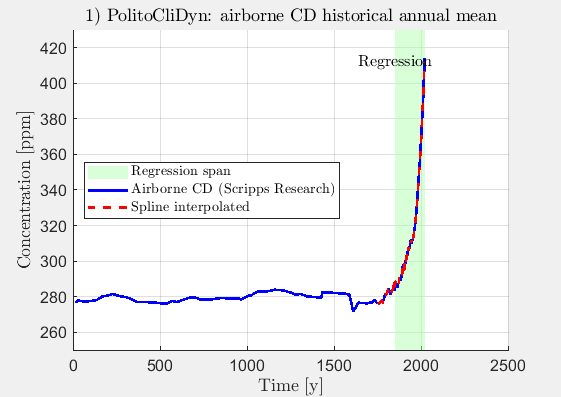

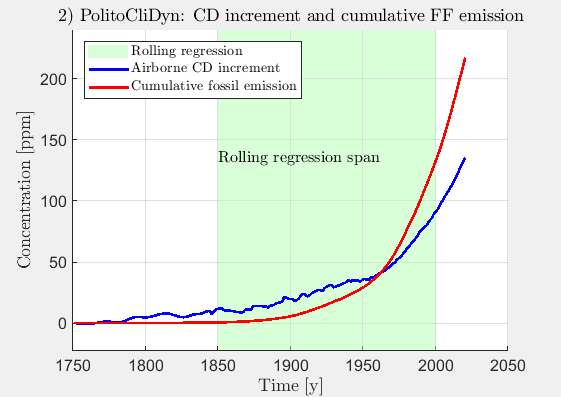

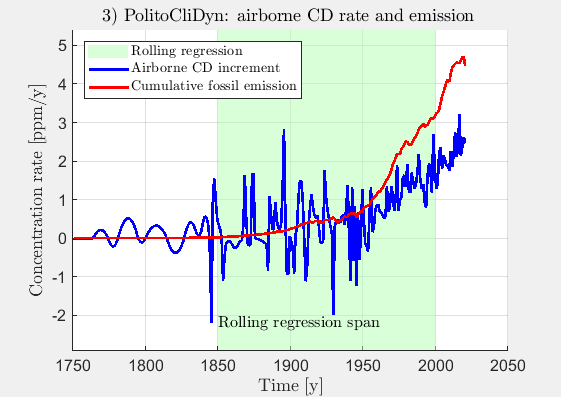

Part I: regression tables to command window
Part I: regression tables to file
Part I: regression time profiles to file
Part I: rolling regression
  Fit step=1, initTime=1850
Part I: integral regression
Part I: difference regression
Part I: cumulative check and residual offset
Part I: writing time profiles and parameters into spreadsheet files 
  Fit step=11, initTime=1860
  Fit step=21, initTime=1870
  Fit step=31, initTime=1880
  Fit step=41, initTime=1890
  Fit step=51, initTime=1900
  Fit step=61, initTime=1910
  Fit step=71, initTime=1920
  Fit step=81, initTime=1930
  Fit step=91, initTime=1940
  Fit step=101, initTime=1950


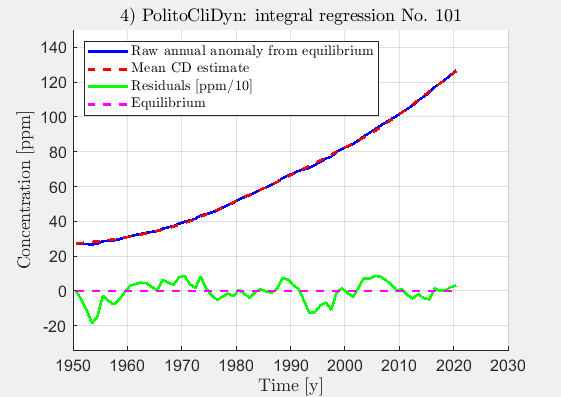

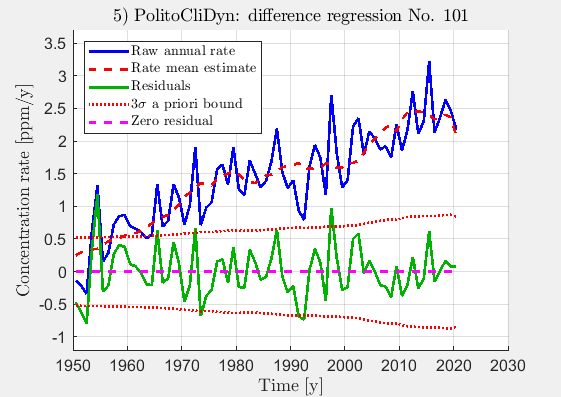

Part I: plotting regression iterations


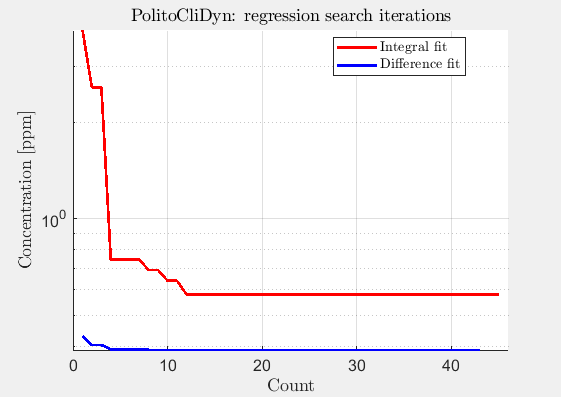

Part I: SELECTED, tables of selected regression 
Table 2: Airborne CD common parameters
      Type        Init. time     Atm. std     Emis. std(%)     Unknowns     Hist. Equil.     Raw RMS  
    __________    __________    __________    ____________    __________    ____________    __________
    {'Common'}    1.9500e+03    1.2000e-01     5.0000e+00     2.0000e+00     2.7962e+02     3.0131e+01
    {'Std'   }           NaN           NaN            NaN            NaN     2.9745e+00            NaN
Table 3: Airborne CD results, regression No. 101
       Regression        Equilibrium      Pole           tau        Input scale     Res. mean     Res. 

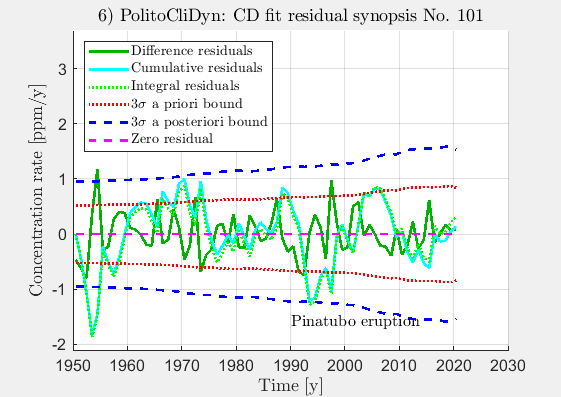

  Fit step=111, initTime=1960
  Fit step=121, initTime=1970
  Fit step=131, initTime=1980
  Fit step=141, initTime=1990
  Fit step=151, initTime=2000
Part I: rolling regression figures
        plotting rolling regression parameters


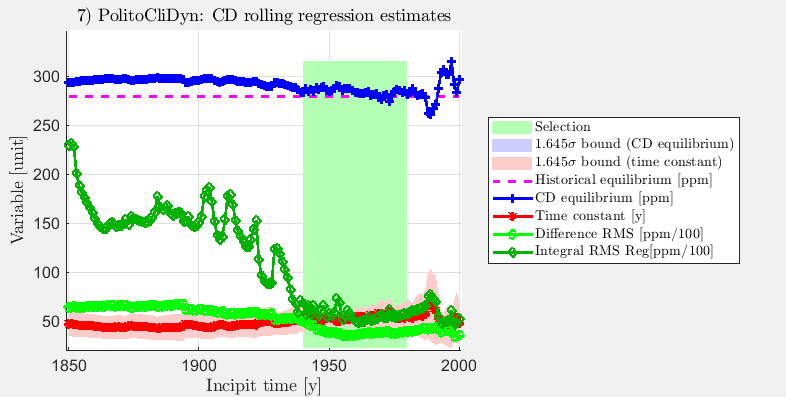

        plotting rolling regression F-test


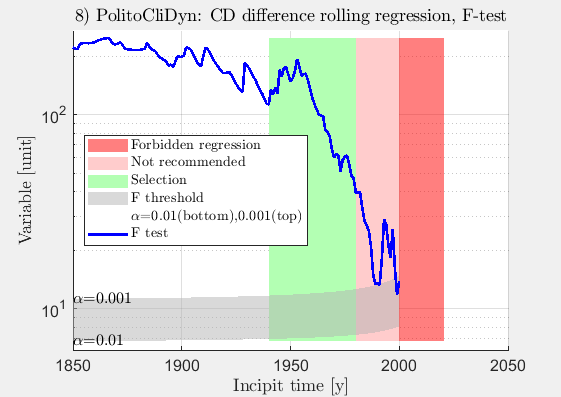

        plotting rolling regression RMS


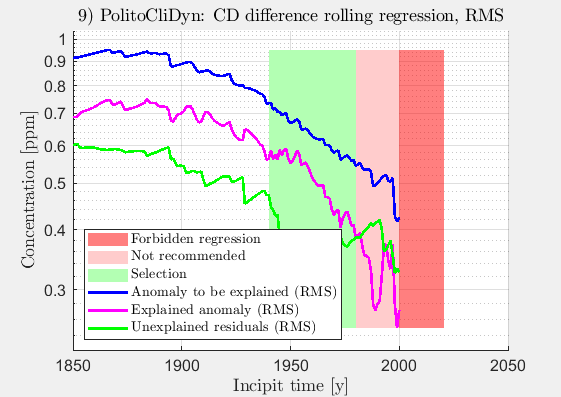


End of Part I
----------------------------------------------------------------


Init_LiveScript;
PolitoCliDyn_1stOrderCC_PartI;

## Part II

Fossil-fuel future proven reserves $r\left(t\right),\;t\ge t_{0\;}$ are predicted by the asymptotic upper limit $r_{\infty }$ of

 
$$r\left(t\right)=r_{\infty } -\left(r_{\infty } -r_{0\;} \right)\exp \;\left(-{s\left(t\right)}^{n\;} \right),s\left(t\right)=\frac{t-t_0 }{\tau \;},r\left(t_0 \right)=r_0$$
 

Unknown parameters  $\tau ,r_{\infty } ,n$  and their std are estimated from historical data (OWID) of the fuel proven reserves (oil, natural gas and coal). Shale oil and natural gas are not included. Historical and predicted reserves are reported in Fig. 2 and Table 1 under different volume/mass units: $\left\lbrack {\textrm{Gm}}^{3\;} ={10}^{9\;} {\mathrm{m}}^{3\;} \right\rbrack$ applies to oil, $\left\lbrack {\textrm{Tm}}^{3\;} ={10}^{12\;} {\mathrm{m}}^{3\;} \right\rbrack$ applies to natural gas and $\left\lbrack \textrm{Pg}={10}^{15\;} \mathrm{g}\right\rbrack$ to coal. The exponent $n>1$, expressing progressive difficulties in reserve finding and proving, balances the asymptotic margin $r_{\infty } -r_{\;} \left(t_p \right),t_p =2020\;y$ and the reserve uncertainty (see Fig. 1). Volume and mass units are scaled to CD concentration [ppm], by fitting historical data of fuel consumption to those of fuel CD emission (OWID) (see Figs. 3 and 4). Table 2 reports the predicted reserves in [ppm] units and the relevant scale factors.

#### Part II run

CheckLiveScriptFolder

PolitoCliDyn: 1st order CC: checking Live Script folder
DONE: PolitoCliDyn_1stOrderCC_LiveScript.mlx found
DONE: Live Script folder



----------------------------------------------------------------
PolitoCliDyn: 1st order CC, airborne CD prediction, Part II
Table 1: User input and actual (corrected) data 
       Type       Ind.era t0    Forbidden t0    SelFit tInit    Rol fit step    Rol fit size
    __________    __________    ____________    ____________    ____________    ____________
    {'Actual'}    1.8500e+03     2.0000e+03      1.9500e+03      1.0000e+00      1.5100e+02 
    {'Input' }           NaN            NaN      1.9500e+03             NaN             NaN 
Part II: reserve prediction tables
Part II: reserve prediction and prediction dynamics exponent search
Part II: oil reserve prediction (no shale oil)
      Reading fossil-fuel reserve data
      Regression and prediction
      Uncertainty band and p

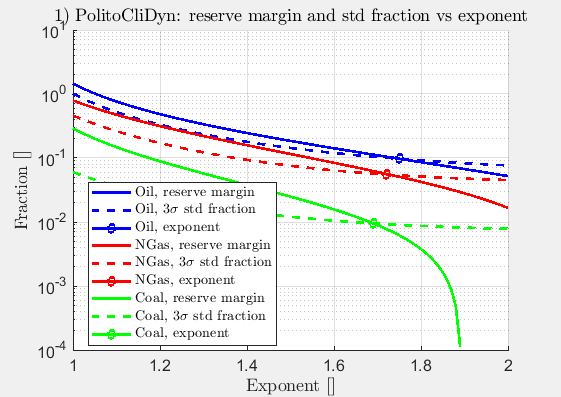

Part II: plotting fuel reserve prediction iterations


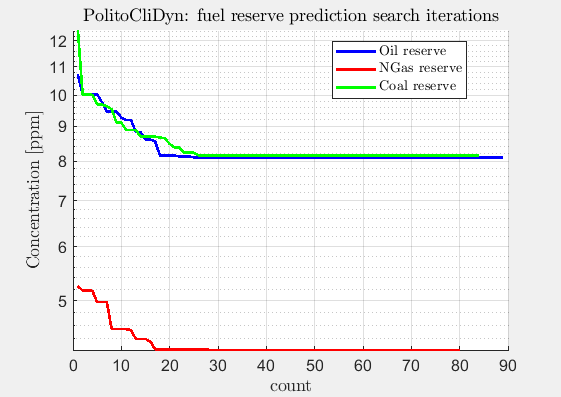

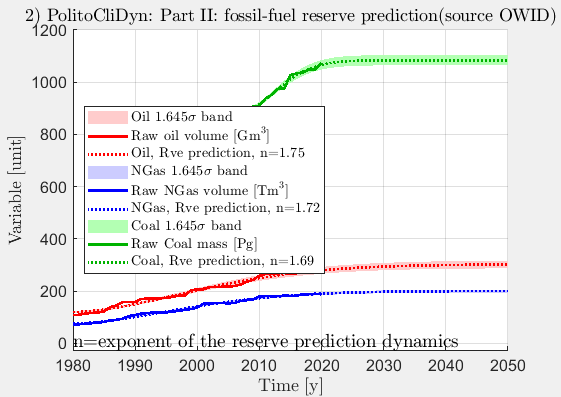

Table 2: Reserve regression results
Units: Gcm=Giga cubic metre, Tcm= Tera cubic metre, GtC = Giga tons of carbon, GtCO2 = Giga tons of CO2
      Fuel type       As. reserve    Amplitude     Time const.[y]     Exponent      Samples      Raw/resRMS
    ______________    ___________    __________    ______________    __________    __________    __________
    {'Oil [Gcm]' }    3.0289e+02     1.8277e+02      2.6384e+01      1.7500e+00    4.1000e+01    5.4003e+01
    {'Std [Gcm] '}    8.9711e+00     8.1146e+00      1.5987e+00      0.0000e+00    0.0000e+00    8.1019e+00
    {'NGas [Tcm]'}    2.0102e+02     1.2490e+02      2.3636e+01      1.7200e+00    4.1000e+01    3.8703e+01
    {'Std [Tcm]' }    3.5066e+00     3.1874e+00      9.3241e-01      0.0000e+00   

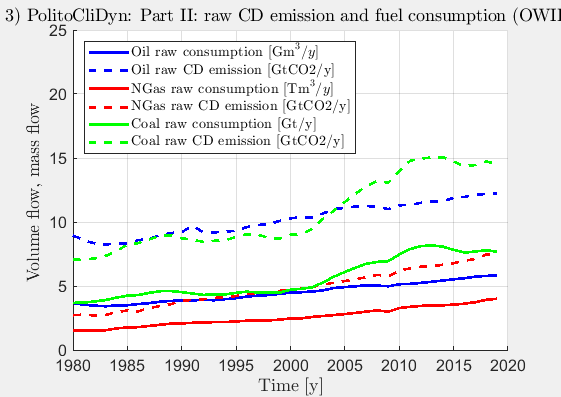

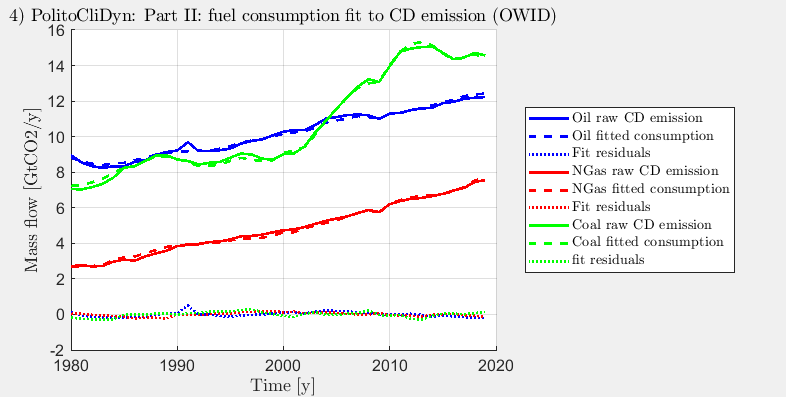

Part II: reserves and uncertainty
Table 3: Predicted reserves
        Fuel type          Bias [GtCO2]    Scale[GtCO2/unit]    Reserve[GtCO2]     Samples      Raw/resRMS [GtCO2]
    ___________________    ____________    _________________    ______________    __________    __________________
    {'Oil [unit=Gcm]' }     2.6626e+00        1.6778e+00          5.1083e+02      4.0000e+01        1.2565e+00    
    {'Std [GtCO2] '   }     1.3601e-01        2.9915e-02          2.4248e+01             NaN        1.4080e-01    
    {'Fraction'       }     5.1079e-02        1.7830e-02          4.7468e-02             NaN        9.8217e+02    
    {'NGas [unit=Tcm]'}    -3.1634e-01        2.0015e+00          4.0203e+02      4.0000e+01        1.4411e+00    
    {'Std [GtCO2]'    }     6.2589e-02      

Init_LiveScript;
PolitoCliDyn_1stOrderCC_PartII;

## Part III

The historical measurements (GCP) of CD emission by fuel combustion  $\breve{c_{\;} } \left(t\right),t\le t_{p\;\;} \;\left\lbrack \textrm{ppm}\;y^{-1\;} \right\rbrack$ of each fuel, oil, natural gas and coal (see Figs.1 to 2) are projected into the future by means of the bell-shaped curve (the *Meixner curve*)

$\begin{array}{l}
\breve{c} \left(t\right)=\frac{a\;\exp \left(\beta \;\sigma \;\left(t\right)\right)}{\cosh^{\;} \left(\;\sigma \;\left(t\right)\right)}+\tilde{c} \left(t\right),\sigma \left(t\right)=\left(t-s\right)\tau^{-1\;} ,t_0 \le t\le t_p \;\\
\hat{c} \left(t\right)=\frac{a\;\exp \left(\beta \;\sigma \;\left(t\right)\right)}{\cosh^{\;} \left(\;\sigma \;\left(t\right)\right)},t_p <t<t_{\textrm{end}} ,r_{\infty } =r\left(t_{p\;} \right)+\int_{t_p }^{t_{\textrm{end}} } \hat{c} \left(\eta \;\right)d\eta +\tilde{r} 
\end{array}$,

up to the measurement errors $\tilde{c} \left(t\right)$ and $\tilde{r}$. The Meixner curve is the product of three factors accounting for *amplitude* ($a$), *skewness* (the exponential function), *shape and location* (the hyperbolic cosine) of past and future CD emissions, where $t_0 \ge 1850\;y$, $t_{p\;} =2022\;y$ , and ${2150\le t}_{\textrm{end}} \le 2250\;y$ is the free end-time of the prediction, to be chosen by users. To be simple and robust (see Figs. 5 to 10), the exponent of the skewness term has been set to zero,$\beta =0$ , implying bell-shape symmetry. Skewness appears to be weakly identifiable, due to highly fluctuating and just increasing raw data (left leg of the bell-shaped curve).

The unknown parameters and their std (see Table 1) are fit on historical emissions and predicted reserve (Fig. 3). As in Part I, a rolling-time  regression has been implemented for recording fit fluctuations and divergence (see Figs. 5 to 10).  The *forbidden region* (red region in figures) is imposed by the F-test (Fig. 11) for $t_0 >2000\;y$ as in Part I and the same applies to the  *not recommended region* (pink in the figures). As a check, the reserve residual  $\tilde{r}$ is shown in Fig.10 to stay within the a priori reserve uncertainty (see Part II). The selected fit is constrained to be the same as in Part I (see Figs. 3 and 4). Amplitude and times of the projected emissions are in Table 2.

Figs.11 and 12 compare the prediction of the finite-reserve total emission with those of CAT and IPCC (retrieved from IIASA). The closest IPCC prediction is that of the SSP 2-4.5, where 2 denotes the class of the scenarios and 4.5 the net radiative forcing $\left\lbrack {\textrm{Wm}}^{-2\;} \right\rbrack$ at 2100 y, which perturbs the energy equilibrium of the Earth's biosphere and consequently the climate.  

#### Part III run

CheckLiveScriptFolder;

PolitoCliDyn: 1st order CC: checking Live Script folder
DONE: PolitoCliDyn_1stOrderCC_LiveScript.mlx found
DONE: Live Script folder



----------------------------------------------------------------
PolitoCliDyn: 1st order CC, airborne CD prediction, Part III
Table 1: User input and actual (corrected) data 
       Type       Ind.era t0    Forbidden t0    SelFit tInit    Rol fit step    Rol fit size
    __________    __________    ____________    ____________    ____________    ____________
    {'Actual'}    1.8500e+03     2.0000e+03      1.9500e+03      1.0000e+00      1.5100e+02 
    {'Input' }           NaN            NaN      1.9500e+03             NaN             NaN 


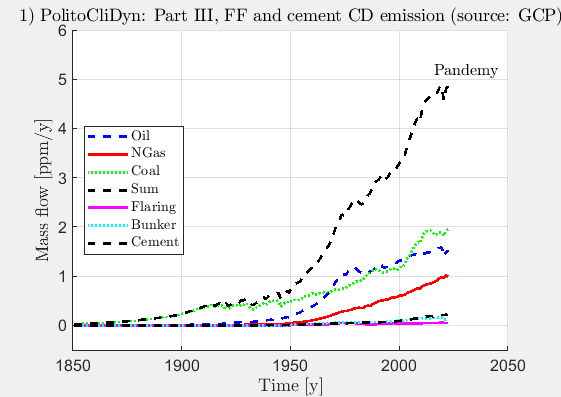

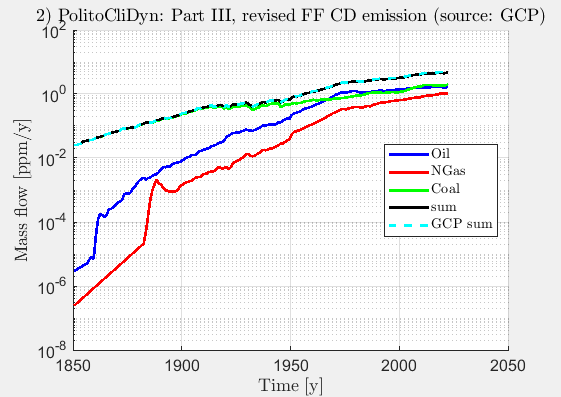

Part III: reading reserve data
Part III: Meixner fit tables to file
Part I: selected fit time profiles to file
Part III: rolling regression and prediction with Meixner curve
  Fit step=1, initTime=1850
  Fit step=11, initTime=1860
  Fit step=21, initTime=1870
  Fit step=31, initTime=1880
  Fit step=41, initTime=1890
  Fit step=51, initTime=1900
  Fit step=61, initTime=1910
  Fit step=71, initTime=1920
  Fit step=81, initTime=1930
  Fit step=91, initTime=1940
  Fit step=101, initTime=1950

SELECTED FIT
      iFuel=1, iBound=1, Fit initTime=1950, Fit Error =1.293855e-01
      iFuel=2, iBound=1, Fit initTime=1950, Fit Error =3.594975e-02
      iFuel=3, iBound=1, Fit initTime=1950, Fit Error =8.628026e-02
      iFuel=1, iBound=2, Fit initTime=1950, Fit Error =1.289102e-01
      iFuel=2, iBound=2, Fit initTime=1950, Fit Error =3.585892e-02
      iFuel=3, iBound=2, Fit initTime=1950, Fit Error =8.598534e-02
      iFuel=1, iBound=3, Fit initTime=1950, Fit Error =1.293135e-01
      iFuel=2, iB

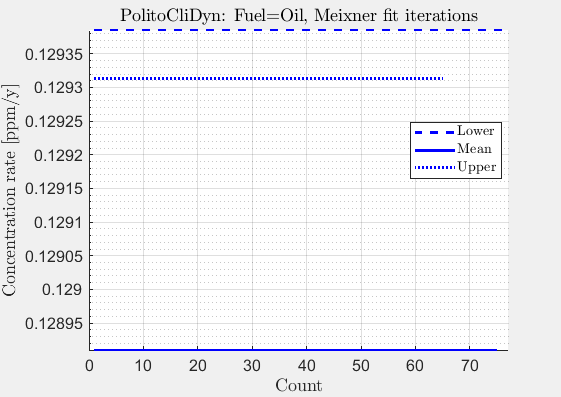

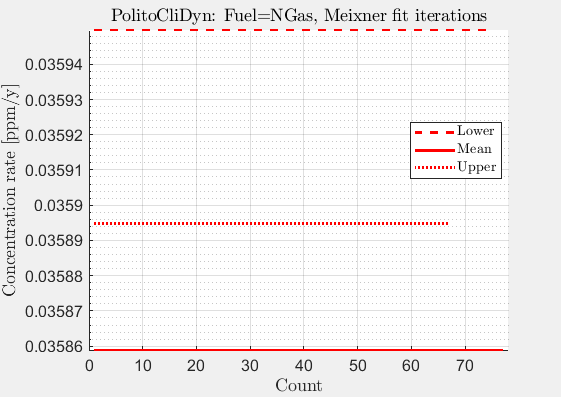

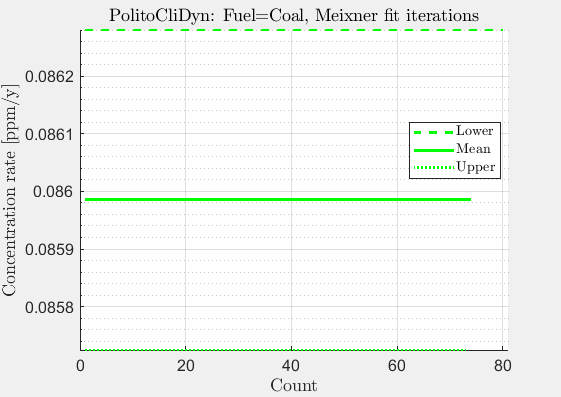

Part III: SELECTED, tables of selected regression 
Table 2: fuel emission fit parameters by Meixner curve
     Fuel/bound      Amplitude     Time const    Peak time      Ampl std      Tau std      Time std       Res RMS  
    _____________    __________    __________    __________    __________    __________    __________    __________
    {'Oil down' }    1.6254e+00    3.0309e+01    2.0125e+03    2.6223e-02    5.5851e-01    4.9594e-01    1.2973e-01
    {'Gas down' }    1.0445e+00    2.6796e+01    2.0281e+03    1.0803e-02    3.2757e-01    1.8325e-01    3.6124e-02
    {'Coal down'}    2.5809e+00    4.3027e+01    2.0546e+03    3.9221e-02    8.5298e-01    4.5507e-01    8.6354e-02
    {'Oil mean' }    1.6330e+00    3.1328e

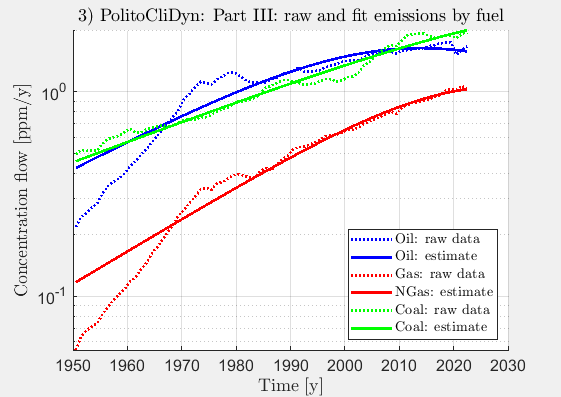

  Fit step=111, initTime=1960
  Fit step=121, initTime=1970
  Fit step=131, initTime=1980
  Fit step=141, initTime=1990
  Fit step=151, initTime=2000

Part III: end of rolling regression
Part III: writing mean parameters into spreadsheet files 
Part III: sum of the selected projected CD emission by fuel


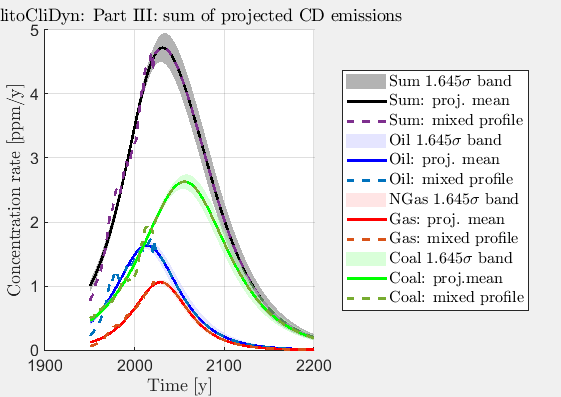

Part III: saving residual RMS as apriori std and optimal init unknowns 
Part III: plotting rolling regression parameters


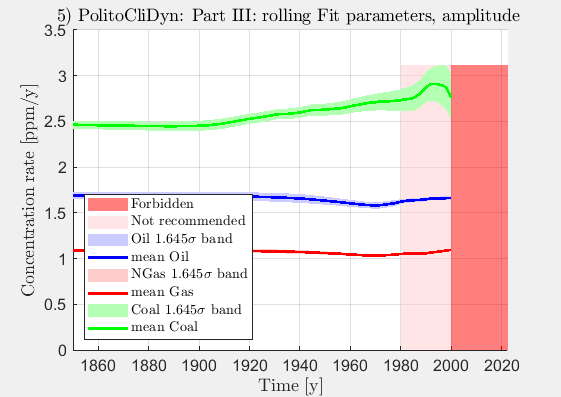

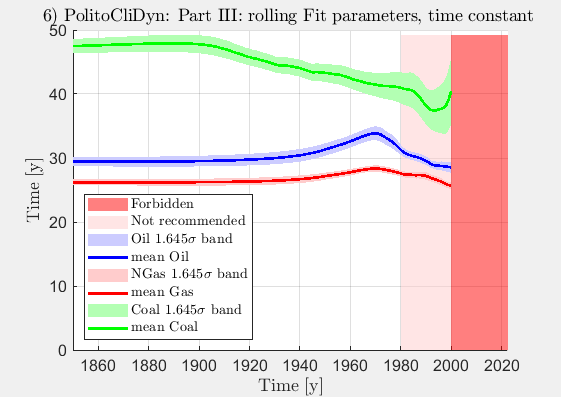

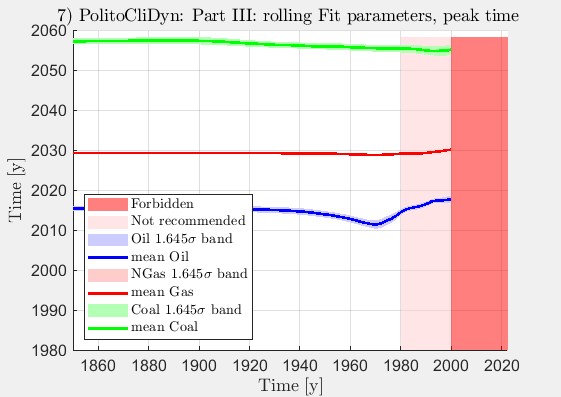

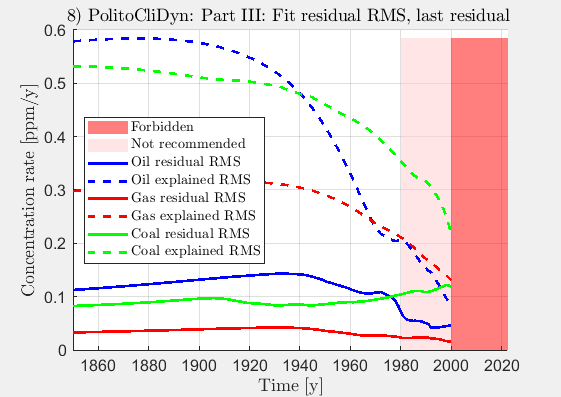

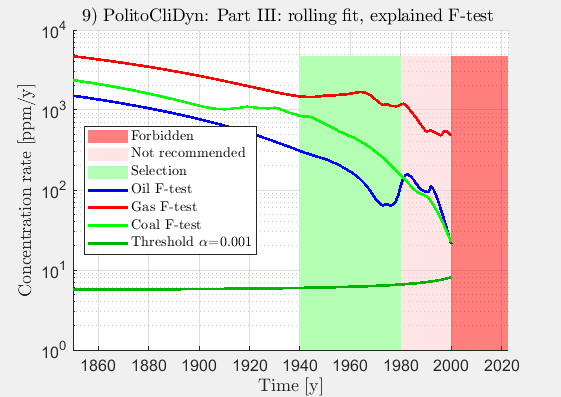

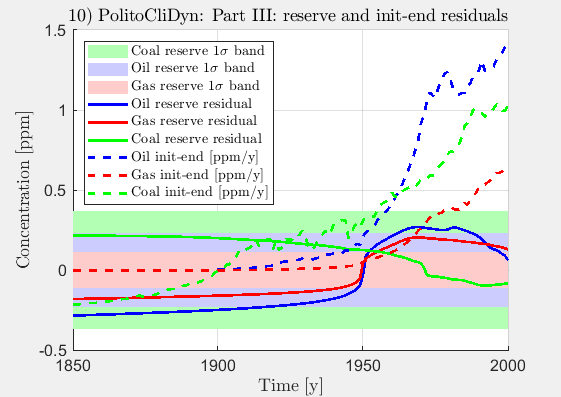

Part III: comparison with CAT (Climate Action Tracker) profiles


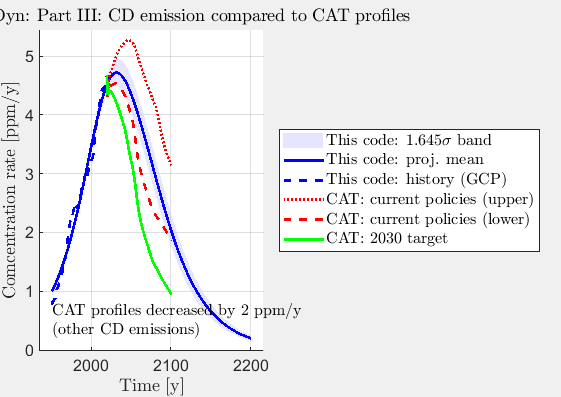

Part III: comparison with IIASA emission profiles


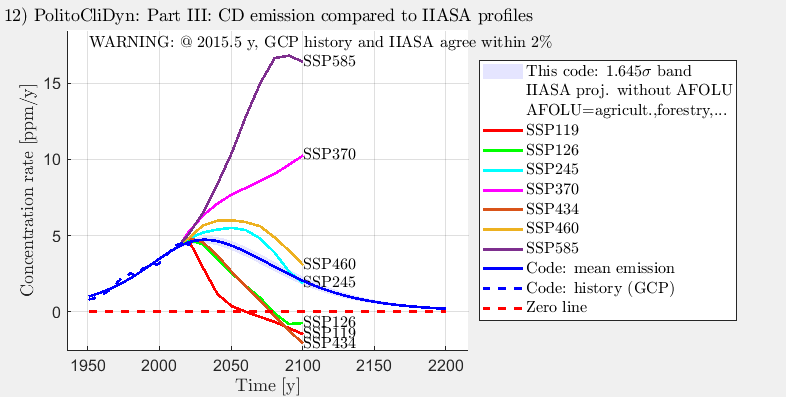


End of Part III
----------------------------------------------------------------


Init_LiveScript;
PolitoCliDyn_1stOrderCC_PartIII;

## Part IV

The prediction of the total finite-reserve emission $u\left(t\right)=\hat{c} \left(t\right)$ is applied to the first-order state equation of Part I for projecting the airborne CD concentration $\hat{x} \left(t\right),t>t_{p\;}$ (Fig.1).  A  rolling-time projection (see Figs. 3 and 4) is again implemented by progressively changing the integration initial time $t_{0\;} \ge 1850\;y$. The initial time `tSelFit` that has been selected by users for graphical plotting and tabulating results (see Figs. 1 and 2), remains the same. Fig. 2 shows graphically the *integration's coherence*. The numerical rate $\Delta \hat{x} \left(t\right)=u\left(t\right)-\Phi {\;}_{\textrm{LO}\;} \left(t\right)\;\left\lbrack \textrm{ppm}\;y^{-1\;} \right\rbrack$  of the projected CD concentration is reconstructed by the difference between the total emission $u\left(t\right)$ and the flow $\Phi {\;}_{\textrm{LO}\;} \left(t\right)$ to land and ocean. Here, the reconstruction error is just* numerical *(see Fig. 2 and Table 2). Rolling-time projection features, like peak time and amplitude of the CD concentration, are coherent with those of the total emission projection in Part III, showing divergence in the pink and red regions.

Fig. 5 compares code results with the IPCC projections driven by the CD emissions in Fig. 12 of Part III. A significant fact is the increasing SSP245 projection (cyan) at 2150 y versus the decreasing finite-reserve projection of the code (blue), notwithstanding the rather close shape of the SSP245 emission (cyan, Fig. 12 of Part III) to the code projection. Fig. 6 shows a diverging discrepancy between the IIASA CD emissions of Fig. 12 of Part III, when integrated by the first-order LTI state equation of Part I (solid lines) and the corresponding IPCC projections of Fig 5 (dashed lines). At first sight, different dynamics have been employed for integrating the projected CD emissions. 

To shed light on the issue, the first-order LTI state equation of Part I is added with a quadratic term of the CD concentration anomaly $\delta x\left(t\right)=x\left(t\right)-\underline{x}$ as follows

$\dot{x} \left(t\right)=-k\left(x\left(t\right)-\underline{x} \right)+{q\left(x\left(t\right)-\underline{x} \right)}^2 +u\left(t\right),x\left(t_{0\;} \right)=x_{0\;}$.

As in Part I, the equation is fit to measurements, here IPCC projections and IIASA  emissions, in three ways: 1) the *difference* fit employs concentration rates (not in figures), 2) the *integral *fit employs the IPCC concentrations in Fig 5, 3) the *cumulative* fit integrates the IIASA emissions with the three unknown parameters $k,\underline{x} ,q$  found by the difference fit. The code focuses on the intermediate scenario SSP460 (Fig. 7, orange color, and Table 1). Both IPCC concentration (top of Fig. 7, blue and red) and rate (mid of Fig. 7, cyan and magenta) are tracked with small residuals. Residuals are plotted in Fig. 7, bottom, added to unit, so as to employ a semilogarithmic scale. The nonzero equilibrium $\delta \underline{x} >0$ (under $k>0,q>0$) is unstable (see Table 1). The estimated value of $k$ (the *first-order pole*) is close to the LTI estimate, thus providing a further check of its significance. 

#### Part IV run

CheckLiveScriptFolder;

PolitoCliDyn: 1st order CC: checking Live Script folder
DONE: PolitoCliDyn_1stOrderCC_LiveScript.mlx found
DONE: Live Script folder



----------------------------------------------------------------
PolitoCliDyn: 1st order CC, airborne CD prediction, Part IV
Part IV: loading user input data and rolling fit timing
Table 1: User input and actual (corrected) data 
       Type       Ind.era t0    Forbidden t0    SelFit tInit    Rol fit step    Rol fit size
    __________    __________    ____________    ____________    ____________    ____________
    {'Actual'}    1.8500e+03     2.0000e+03      1.9500e+03      1.0000e+00      1.5100e+02 
    {'Input' }           NaN            NaN      1.9500e+03             NaN             NaN 
Part IV: Airborne CD projection with 1st-order LTI CD dynamics 
  Fit step=1, initTime=1850
      reading Part I model parameters
      reading predicted Part III FF CD emissions
      reading 

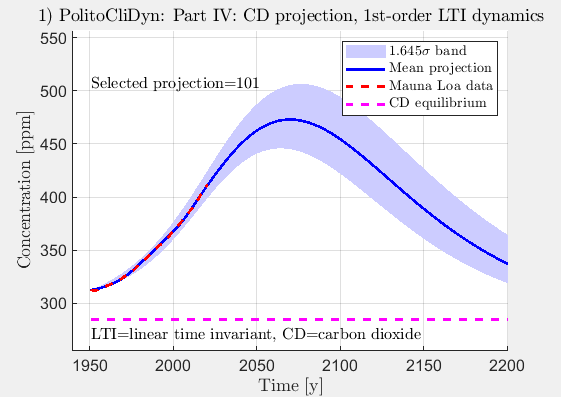

      checking coherence of airborne CD rate


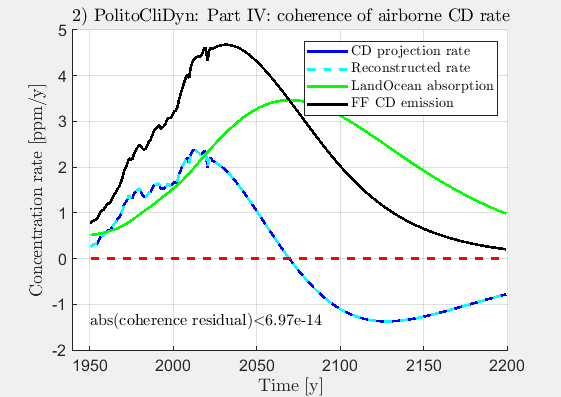

  Fit step=111, initTime=1960
  Fit step=121, initTime=1970
  Fit step=131, initTime=1980
  Fit step=141, initTime=1990
  Fit step=151, initTime=2000
Part IV: airborne CD projection peaks and timing


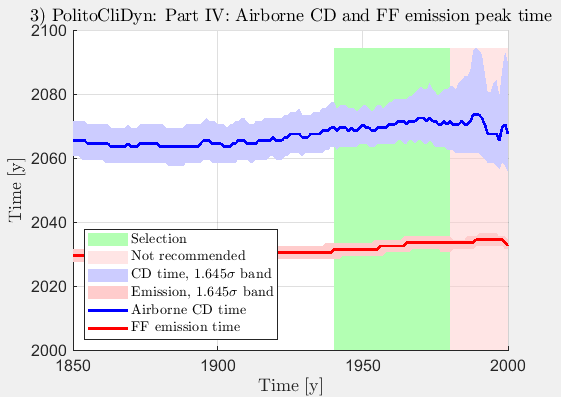

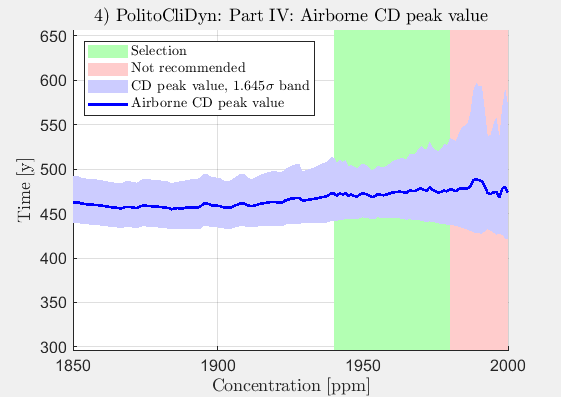

Part IV: comparison of airborne CD projection with IPCC profiles


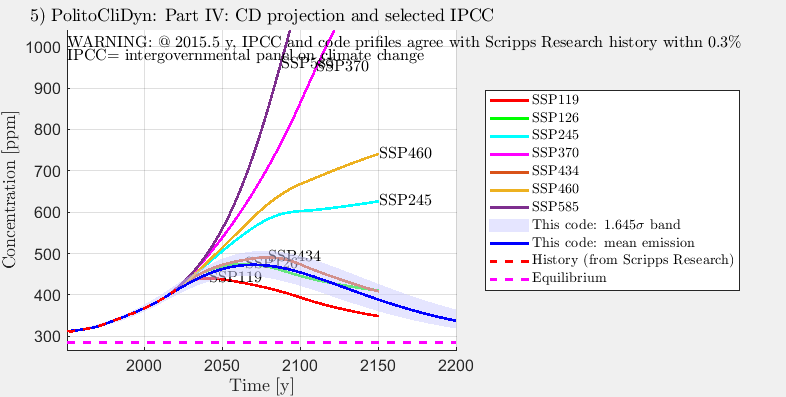

Part IV: recall, fossil fuel CD emissions projections (source: IPCC)
Part IV: IIASA DC emissions integrated with 1st-order LTI CD dynamics 


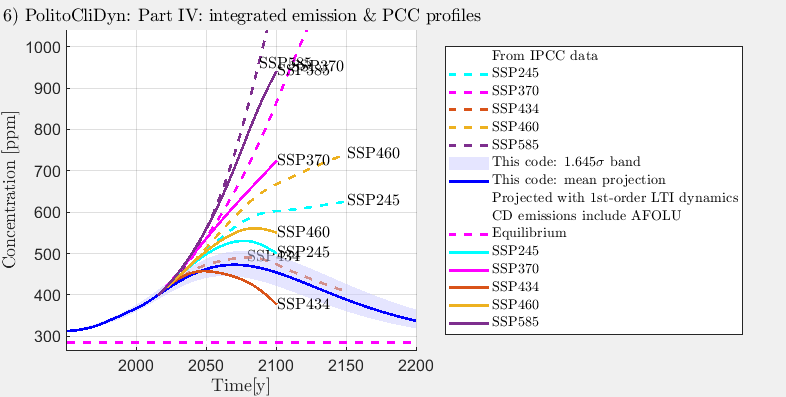

Part IV: IPCC CD projection rate, CD emission and flow to land/ocean
Part IV: fitting IPCC CD projections with 1st-order quadratic dynamics
      1) difference fit
      2) cumulative fit
      3) integral fit
Part I: plotting difference and integral quadratic fit iterations


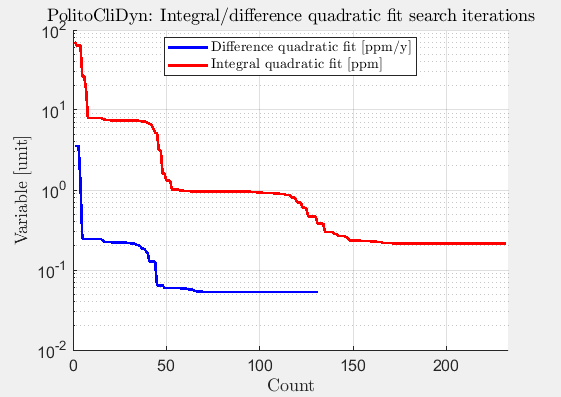

Part IV: plotting fit and residuals, 1st-order quadratic dynamics


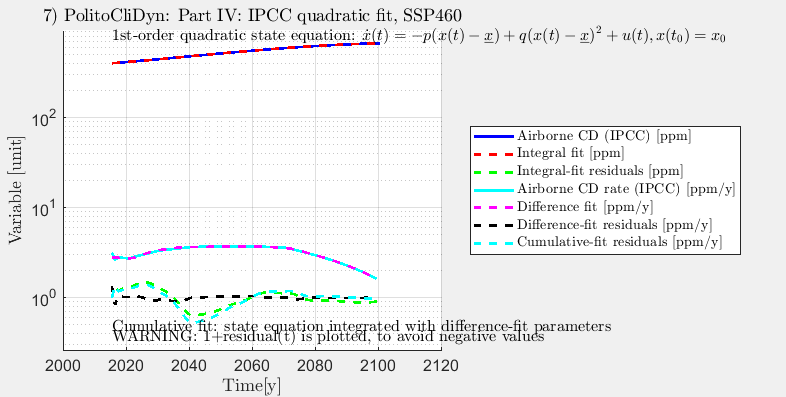

Table 2: 1st-order quadratic equation fit results (IPCC data)
            Parameter             Difference[ppm/y]    Cumulative[ppm]    Integral[ppm]    Difference LTI
    __________________________    _________________    _______________    _____________    ______________
    {'Equilibrium(Eql) [ppm]'}       2.4063e+02           2.4063e+02       2.3673e+02        2.9653e+02  
    {'Pole [1/y]'            }       1.9985e-02           1.9985e-02       1.9754e-02        2.0807e-02  
    {'Quadratic[(yxppm)^-1]' }       4.0154e-05           4.0154e-05       3.9272e-05        0.0000e+00  
    {'Unused'                }              NaN                  NaN              NaN               NaN  
    {'Residual RMS [unit]'   }       5.3002e-02           2.2693e-01       2.1842e-01               NaN  
    {'Variable RMS[unit]' 

Init_LiveScript;
PolitoCliDyn_1stOrderCC_PartIV